%% Data sets
datasetname = 'feb11-imaging-intensity-calibration.mat';
if exist(datasetname) 
    load(datasetname); 
end

% % 11 February, Top Hybrid, Known run
% filenames1 = {'02-11-2016_19_52_39_top'	'02-11-2016_19_51_50_top'	'02-11-2016_19_51_00_top'	'02-11-2016_19_50_11_top'	'02-11-2016_19_48_32_top'	'02-11-2016_19_47_43_top'	'02-11-2016_19_46_53_top'	'02-11-2016_19_46_04_top'	'02-11-2016_19_45_14_top'	'02-11-2016_19_44_25_top'	'02-11-2016_19_42_46_top'	'02-11-2016_19_41_56_top'	'02-11-2016_19_41_07_top'	'02-11-2016_19_40_17_top'	'02-11-2016_19_39_28_top'	'02-11-2016_19_38_38_top'	'02-11-2016_19_37_49_top'	'02-11-2016_19_36_03_top'	'02-11-2016_19_35_14_top'	'02-11-2016_19_33_35_top'	'02-11-2016_19_32_45_top'	'02-11-2016_19_31_06_top'	'02-11-2016_19_29_27_top'	'02-11-2016_19_28_38_top'	'02-11-2016_19_27_48_top'};
% imagepowers1 = [0.600000000000000	1	2.80000000000000	2	1.80000000000000	3.50000000000000	2.20000000000000	5	1.40000000000000	0.800000000000000	1.60000000000000	4	4.50000000000000	3	2.40000000000000	2.60000000000000	1.20000000000000	2.80000000000000	1	1.40000000000000	3	2	2.60000000000000	0.800000000000000	4];
% 
% % 11 February, Top Hybrid, Potential Run
% filenames2 = {'02-11-2016_21_11_39_top'	'02-11-2016_21_10_49_top'	'02-11-2016_21_10_00_top'	'02-11-2016_21_09_11_top'	'02-11-2016_21_08_21_top'	'02-11-2016_21_06_03_top'	'02-11-2016_21_05_13_top'	'02-11-2016_21_04_24_top'	'02-11-2016_21_03_35_top'	'02-11-2016_21_02_45_top'	'02-11-2016_21_02_01_top'	'02-11-2016_21_01_11_top'	'02-11-2016_20_48_59_top'	'02-11-2016_20_48_09_top'	'02-11-2016_20_47_20_top'	'02-11-2016_20_46_30_top'	'02-11-2016_20_45_41_top'	'02-11-2016_20_44_51_top'	'02-11-2016_20_42_57_top'	'02-11-2016_20_42_08_top'	'02-11-2016_20_41_18_top'	'02-11-2016_20_40_29_top'	'02-11-2016_20_39_18_top'	'02-11-2016_20_37_39_top'	'02-11-2016_20_36_50_top'	'02-11-2016_20_36_00_top'	'02-11-2016_20_35_11_top'	'02-11-2016_20_34_21_top'	'02-11-2016_20_33_32_top'	'02-11-2016_20_32_42_top'	'02-11-2016_20_28_45_top'	'02-11-2016_20_27_56_top'	'02-11-2016_20_27_06_top'	'02-11-2016_20_26_17_top'	'02-11-2016_20_25_27_top'	'02-11-2016_20_24_38_top'	'02-11-2016_20_23_48_top'};
% imagepowers2 = [0.900000000000000	0.850000000000000	0.800000000000000	1	0.750000000000000	4.50000000000000	3.50000000000000	2.50000000000000	1.50000000000000	4	3	2	1.10000000000000	1.05000000000000	1	0.950000000000000	0.900000000000000	0.850000000000000	0.800000000000000	0.750000000000000	0.700000000000000	0.650000000000000	0.750000000000000	0.550000000000000	0.800000000000000	1	1.05000000000000	0.950000000000000	0.850000000000000	1.10000000000000	0.900000000000000	0.850000000000000	0.800000000000000	0.750000000000000	0.700000000000000	0.650000000000000	0.600000000000000];
% 
% % Settings
% sett.crop = {'rect',268,217,170,300};
% sett.bg = {'avg',20};
% sett.Nsat = Inf;
% 
% % Test few images to make sure for crop region, etc.
% temp = imagedata(filenames1{2},'plot',{1},'crop',sett.crop,'bg',sett.bg,'Nsat',sett.Nsat);
% % Fields needed from temp - filepath, imagetype, od2, wa2, woa2, bgavg
% 
% % Import all data
% d1 = struct([]);
% for i = 1:length(filenames1)
%     temp = imagedata(filenames1{i},'plot',{0},'crop',sett.crop,'bg',sett.bg,'Nsat',sett.Nsat);
%     d1(i).od = temp.od2;
%     d1(i).wa = temp.wa2;
%     d1(i).woa = temp.woa2;
%     d1(i).filename = temp.filename;
%     d1(i).imagetype = temp.imagetype;
%     d1(i).bg = temp.bgavg;
%     d1(i).impower = imagepowers1(i);
% end
% 
% d2 = struct([]);
% for i = 1:length(filenames2)
%     temp = imagedata(filenames2{i},'plot',{0},'crop',sett.crop,'bg',sett.bg,'Nsat',sett.Nsat);
%     d2(i).od = temp.od2;
%     d2(i).wa = temp.wa2;
%     d2(i).woa = temp.woa2;
%     d2(i).filename = temp.filename;
%     d2(i).imagetype = temp.imagetype;
%     d2(i).bg = temp.bgavg;
%     d2(i).impower = imagepowers2(i);
% end
% 
% save(datasetname,'d1','d2','sett');

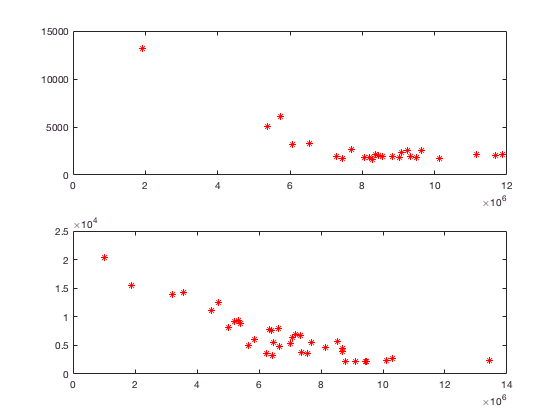

% Fudge from total atom numbers with average imaging intensity
ODc1 = arrayfun(@(x) sum(x.od(:)),d1);
ODc2 = arrayfun(@(x) sum(x.od(:)),d2);
DI1 = arrayfun(@(x) sum(x.woa(:)-x.wa(:)),d1);
DI2 = arrayfun(@(x) sum(x.woa(:)-x.wa(:)),d2);

figure;
subplot(2,2,[1,2]); plot(DI1,ODc1,'r*');
subplot(2,2,[3,4]); plot(DI2,ODc2,'r*');

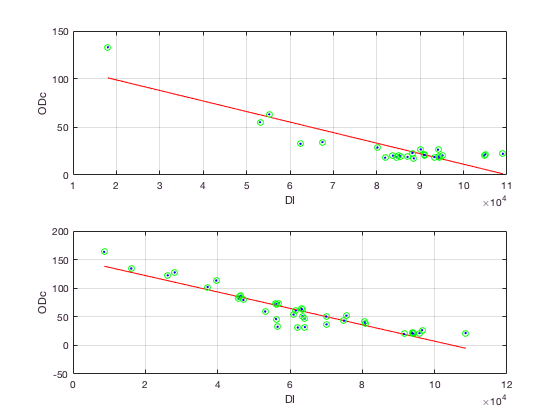

% Fudge from particular row 
row_num = fix(size(d1(1).od,1)/2);
row_num = 150;
ODc1 = arrayfun(@(x) sum(x.od(row_num,:)),d1);
ODc2 = arrayfun(@(x) sum(x.od(row_num,:)),d2);
DI1 = arrayfun(@(x) sum(x.woa(row_num,:)-x.wa(row_num,:)),d1);
DI2 = arrayfun(@(x) sum(x.woa(row_num,:)-x.wa(row_num,:)),d2);

figure;
ax1 = subplot(2,2,[1,2]); [outp,fitres,gof] = fitline_saturation_intensity(DI1,ODc1,'plot',{1,ax1},'maxDI',20e4);
ax2 = subplot(2,2,[3,4]); [outp,fitres,gof] = fitline_saturation_intensity(DI2,ODc2,'plot',{1,ax2},'maxDI',20e4);

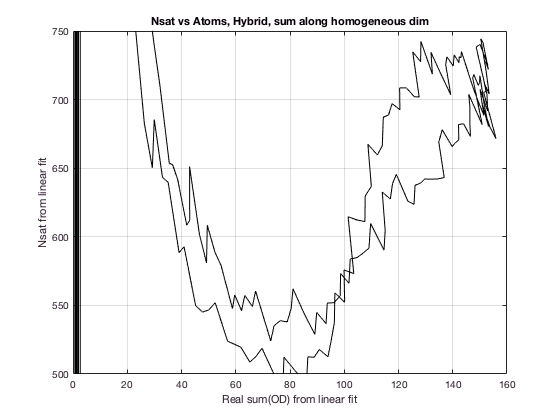

% Fudge vs row (atom number at some row)
ys = (1:300)';
fitresults = zeros(length(ys),2);
for i = 1:length(ys)
    t2 = arrayfun(@(x) sum(x.od(ys(i),:)),d2);
    t1 = arrayfun(@(x) sum(x.woa(ys(i),:)-x.wa(ys(i),:)),d2);
    outp = fitline_saturation_intensity(t1,t2,'plot',{0},'maxDI',20e4);
    fitresults(i,1) = outp.ODr;
    fitresults(i,2) = outp.Nsat;
end

figure;
plot(fitresults(:,1), fitresults(:,2),'k-');
xlabel('Real sum(OD) from linear fit'); ylabel('Nsat from linear fit'); title('Nsat vs Atoms, Hybrid, sum along homogeneous dim'); grid on;
xlim([0 160]); ylim([500,750]);

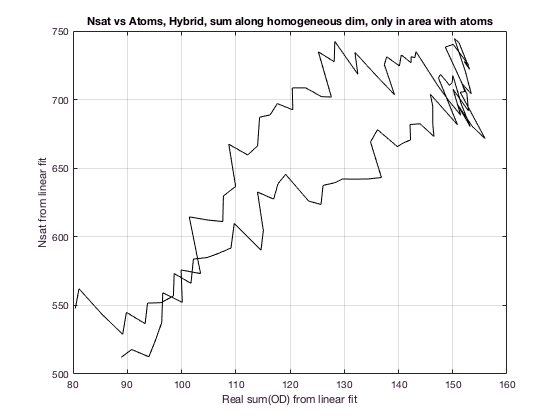

% Fudge vs row (atom number at some row)
ys = (100:210)';
fitresults = zeros(length(ys),2);
for i = 1:length(ys)
    t2 = arrayfun(@(x) sum(x.od(ys(i),:)),d2);
    t1 = arrayfun(@(x) sum(x.woa(ys(i),:)-x.wa(ys(i),:)),d2);
    outp = fitline_saturation_intensity(t1,t2,'plot',{0},'maxDI',20e4);
    fitresults(i,1) = outp.ODr;
    fitresults(i,2) = outp.Nsat;
end

figure;
plot(fitresults(:,1), fitresults(:,2),'k-');
xlabel('Real sum(OD) from linear fit'); ylabel('Nsat from linear fit'); title('Nsat vs Atoms, Hybrid, sum along homogeneous dim, only in area with atoms'); grid on;
xlim([80 160]); ylim([500,750]);

% Fudge vs row  cols: 80:120 into 4 chunks  rows: 100:210
ys = (100:210)';
fitresults = zeros(length(ys)*4,2);
for i = 1:length(ys)
    t2 = arrayfun(@(x) sum(x.od(ys(i),81:90)),d2);
    t1 = arrayfun(@(x) sum(x.woa(ys(i),81:90)-x.wa(ys(i),81:90)),d2);
    outp = fitline_saturation_intensity(t1,t2,'plot',{0},'maxDI',20e4);
    fitresults(i,1) = outp.ODr;
    fitresults(i,2) = outp.Nsat;
end
for i = 1:length(ys)
    t2 = arrayfun(@(x) sum(x.od(ys(i),91:100)),d2);
    t1 = arrayfun(@(x) sum(x.woa(ys(i),91:100)-x.wa(ys(i),91:100)),d2);
    outp = fitline_saturation_intensity(t1,t2,'plot',{0},'maxDI',20e4);
    fitresults(i+length(ys),1) = outp.ODr;
    fitresults(i+length(ys),2) = outp.Nsat;
end
for i = 1:length(ys)
    t2 = arrayfun(@(x) sum(x.od(ys(i),101:110)),d2);
    t1 = arrayfun(@(x) sum(x.woa(ys(i),101:110)-x.wa(ys(i),101:110)),d2);
    outp = fitline_saturation_intensity(t1,t2,'plot',{0},'maxDI',20e4);
    fitresults(i+length(ys)*2,1) = outp.ODr;
    fitresults(i+length(ys)*2,2) = outp.Nsat;
end
for i = 1:length(ys)
    t2 = arrayfun(@(x) sum(x.od(ys(i),111:120)),d2);
    t1 = arrayfun(@(x) sum(x.woa(ys(i),111:120)-x.wa(ys(i),111:120)),d2);
    outp = fitline_saturation_intensity(t1,t2,'plot',{0},'maxDI',20e4);
    fitresults(i+length(ys)*3,1) = outp.ODr;
    fitresults(i+length(ys)*3,2) = outp.Nsat;
end



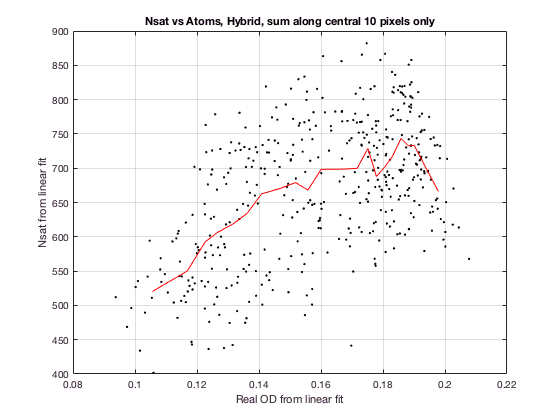

% Plots for above calculations
fitresults(:,1) = fitresults(:,1)/10; % OD per pixel
[sODr,indices] = sort(fitresults(:,1));
sNsat = fitresults(:,2); sNsat = sNsat(indices);
ODr_bin = [];
Nsat_bin = [];
binnum = 20;

for i = 1:binnum:size(fitresults,1)-binnum
    ODr_bin = [ODr_bin;mean(sODr(i:i+binnum-1))];
    Nsat_bin = [Nsat_bin;mean(sNsat(i:i+binnum-1))];
end

figure;
plot(fitresults(:,1), fitresults(:,2),'k.');
hold on;
plot(ODr_bin,Nsat_bin,'r-'); hold off;
xlabel('Real OD from linear fit'); ylabel('Nsat from linear fit'); title('Nsat vs Atoms, Hybrid, sum along central 10 pixels only'); grid on;

% Use 2 fudge factors, alpha and Isat


% Estimate error in atom number as a function of real density


